moving = readMedicalVolume("1\");
fixed = readMedicalVolume("2\");

% set the window for the abdomen 
wl = 50;
ww = 400;

fixed = applyWindowLevel(fixed.vol,ww,wl);
moving = applyWindowLevel(moving.vol,ww,wl);

tic
fixedVol = fixed;
movingVol = moving;
% fixedVol = gpuArray(fixed);
% movingVol = gpuArray(moving);
[D,movingRegVol] = imregdemons(movingVol, fixedVol,[100 50 25],'AccumulatedFieldSmoothing',0.5);
toc

Elapsed time is 47.889349 seconds.


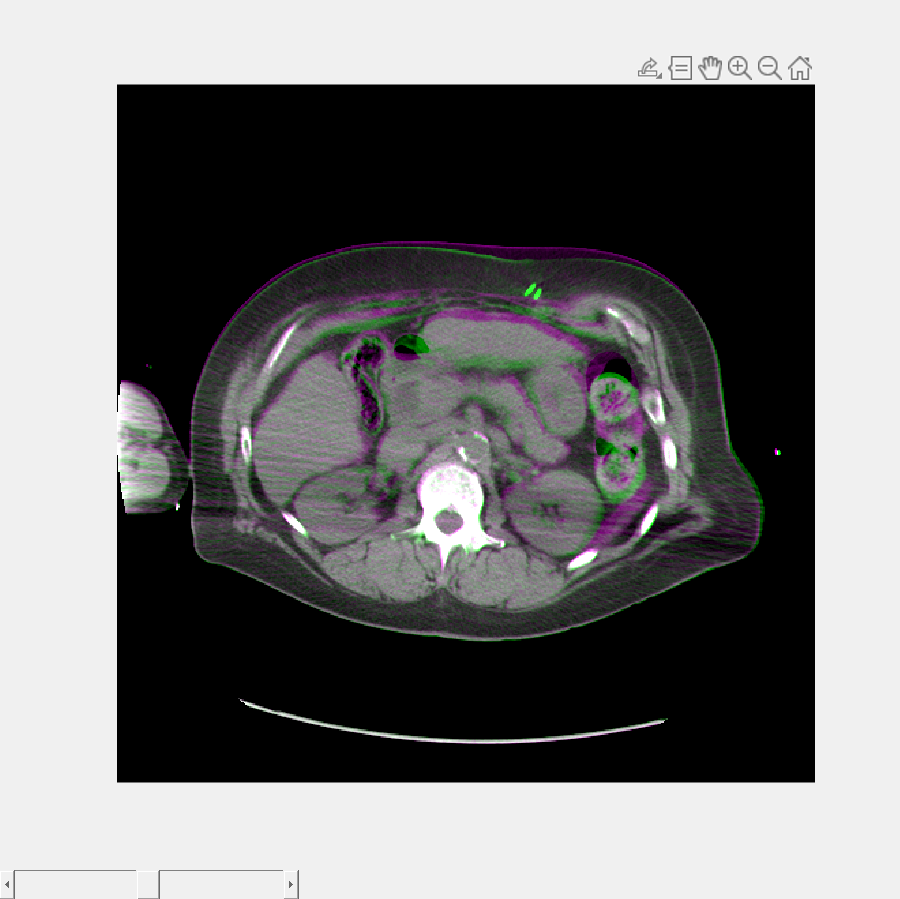

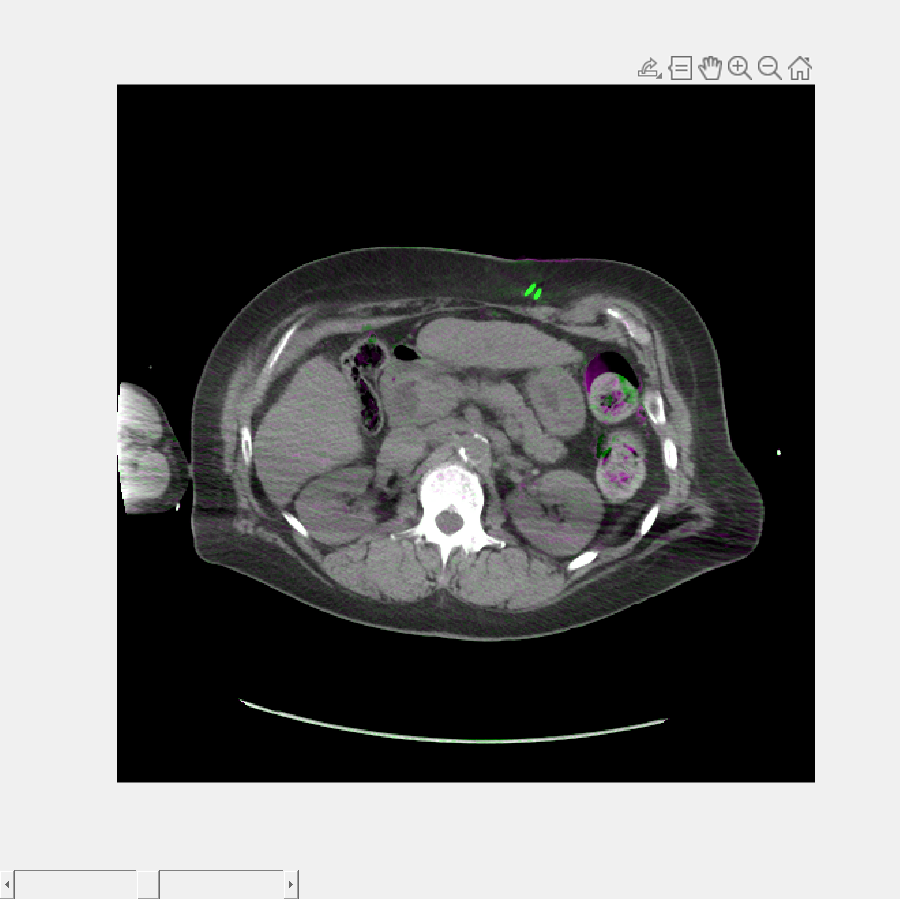

fusedSliceViewer(fixedVol, movingVol, "Before Registration");

fusedSliceViewer(fixedVol, movingRegVol, "After Registration");